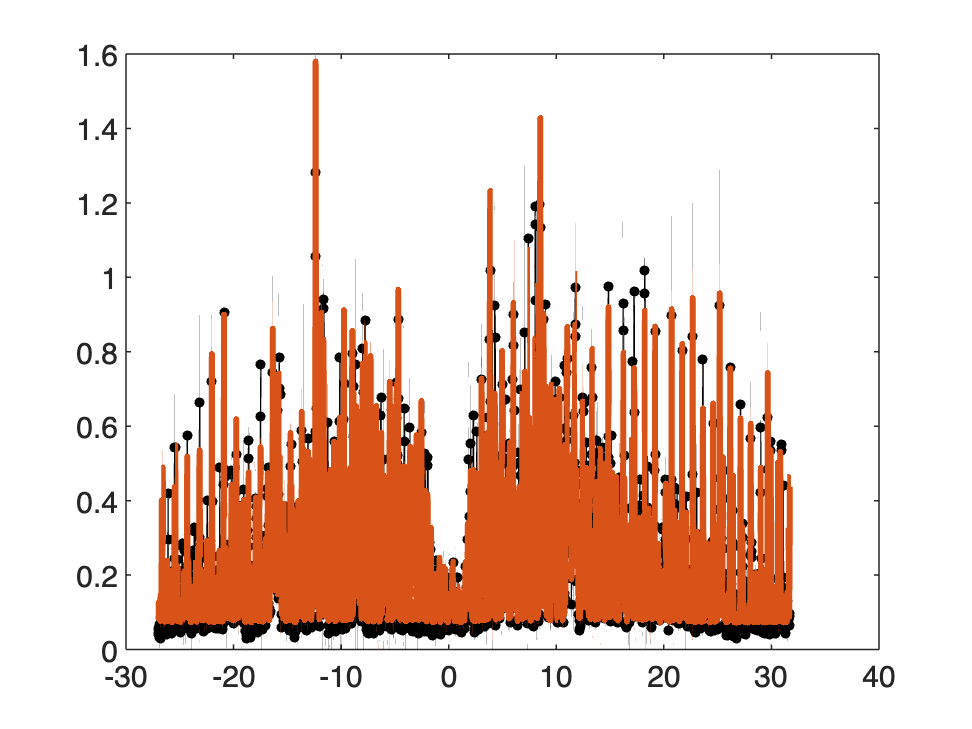

A1 = 1721 + 532 +0.8; % K + ~B 
B1 = 532 + 124/2;
C1 = 532 - 124/2 +0.8;

% S1 - S0
dA1 = 3.91-6.48;
dB1 = -6.48 -2.83/2;
dC1 = -6.48 +2.83/2;


Temp = 3.2;
Th = 90;
Ph = 0;
nu0 = 923604613;
Shift = 0;
GW = 37; 
LW = 5.2; 
Int1 = 9.13*1000;
Offset = 0.071;
x = PmtFla1(:,1);
y = PmtFla1(:,2);
model = Int1*AsymRotor(x, A1, B1, C1, dA1, dB1, dC1, nu0 + Shift, Temp, Th, Ph, GW, LW, 50, 1, 2, 15/17)+Offset;

figure; plot((x-(nu0+Shift))/1000, y,'Marker','.','MarkerSize',10,'Color','k');
hold on;
plot((x-(nu0+Shift))/1000, model,'LineWidth',2)